# Complex environment - Constant current


Starting wave glider path planning with dynamic obstacles...
Goal reached in 6764 iterations with wave glider dynamics.
Total time: 1352.8 seconds
Wave Glider Path Stats:
  Path length: 157.96 m
  Total time: 1352.8 s
  Average ground speed: 0.12 m/s
  Waypoints: 6261
  Total turning: 54.63 rad (3129.9 deg)

--- Wave Glider Parameters ---
Average Speed: 0.21 m/s
Turning Radius: 1.50 m
Max Turn Rate: 0.140 rad/s (8.0 deg/s)


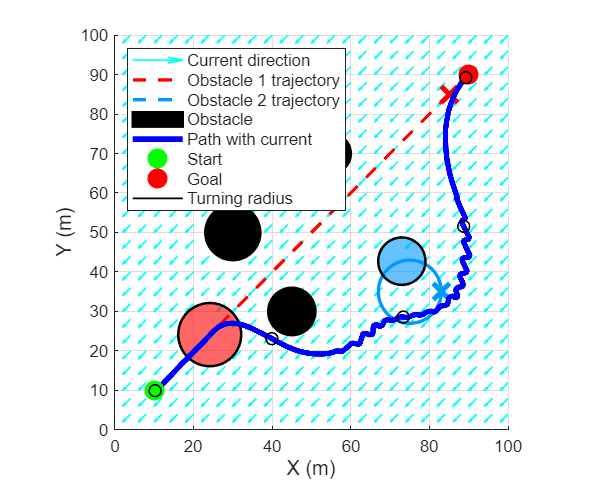

function apf_path_planning_wave_glider()
    % Artificial Potential Field Method for Local Path Planning
    % With Wave Glider Dynamics
    % Complex environment with constant current

    % Clear workspace
    clear; close all; clc;

    % Environment setup - 100x100m
    field_size = 100;     % Size of the field
    resolution = 0.5;     % Grid resolution (increased for larger field)
    x = 0:resolution:field_size;
    y = 0:resolution:field_size;
    [X, Y] = meshgrid(x, y);

    % Robot parameters -
    start_pos   = [10, 10];      % Starting position
    goal_pos    = [90, 90];      % Goal position
    robot_radius = 1.53;          % Robot radius for collision detection

    % WAVE GLIDER DYNAMICS PARAMETERS
    wave_glider.avg_speed = 0.21;        % Average speed (m/s)
    wave_glider.turning_radius = 1.5;   % Minimum turning radius (m)
    wave_glider.max_turn_rate = wave_glider.avg_speed / wave_glider.turning_radius; % rad/s

    % DYNAMIC OBSTACLES SETUP
    % Each obstacle: [x_initial, y_initial, radius, vx, vy, motion_type, param1, param2, param3, param4]
    % Motion types: 1=linear, 2=circular, 4=stationary
    dynamic_obstacles = [
        % Head-on obstacle: starts near goal, moves toward start
        85, 85, 8, -0.045, -0.045, 1, 0, 0, 0, 0;  % Linear motion from goal to start
        
        % Circular obstacle in corner
        75, 35, 6, 0, 0, 2, 8, 0.15, 0, 0;  % Circular
        
        % Static obstacles (out of the way)
        30, 50, 7, 0, 0, 4, 0, 0, 0, 0;    % Stationary
        55, 70, 5, 0, 0, 4, 0, 0, 0, 0;    % Stationary
        45, 30, 6, 0, 0, 4, 0, 0, 0, 0;    % Stationary
    ];

    % APF parameters
    k_att = 0.5;        % Attractive force gain
    k_rep = 15;       % Repulsive force gain
    d0    = 20;       % Influence distance of obstacles 
    dt    = 0.2;        % Time step for wave glider dynamics (s)
    max_iterations = 10000; % Increased for larger environment

    % Current (environment) parameters
    U_current = 0.1;        % Current speed (m/s)
    theta_rad = 5*pi/4;          % Direction (0 rad = to the right/east)
    k_env     = 2;        % Weight of environmental influence

    % Current vector (constant everywhere)
    [Ux, Uy, phi_current] = uniform_current_field(X, Y, U_current, theta_rad);

    % Calculate potentials (for visualization only - using initial obstacle positions)
    initial_obstacles = update_obstacle_positions(dynamic_obstacles, 0);
    U_att   = attractive_potential(X, Y, goal_pos, k_att);
    U_rep   = repulsive_potential(X, Y, initial_obstacles, k_rep, d0);
    U_env   = environmental_potential(X, Y, Ux, Uy, k_env);  % linear potential
    U_total = U_att + U_rep + U_env;

    % Path planning with wave glider dynamics and dynamic obstacles
    [path_with_dynamics, obstacle_history] = path_planning_wave_glider(start_pos, goal_pos, dynamic_obstacles, ...
        k_att, k_rep, d0, dt, max_iterations, robot_radius, k_env, Ux, Uy, wave_glider);

    % Display wave glider parameters
    fprintf('\n--- Wave Glider Parameters ---\n');
    fprintf('Average Speed: %.2f m/s\n', wave_glider.avg_speed);
    fprintf('Turning Radius: %.2f m\n', wave_glider.turning_radius);
    fprintf('Max Turn Rate: %.3f rad/s (%.1f deg/s)\n', wave_glider.max_turn_rate, rad2deg(wave_glider.max_turn_rate));

    % Visualization
    visualize_results(X, Y, U_total, U_att, U_rep, U_env, start_pos, goal_pos, ...
        dynamic_obstacles, path_with_dynamics, obstacle_history, field_size, Ux, Uy, phi_current, wave_glider);
end

%% Dynamic Obstacle Update Function
function current_obstacles = update_obstacle_positions(dynamic_obstacles, t)
    current_obstacles = zeros(size(dynamic_obstacles, 1), 3); % [x, y, radius]
    
    for i = 1:size(dynamic_obstacles, 1)
        x0 = dynamic_obstacles(i, 1);        % Initial/center x position
        y0 = dynamic_obstacles(i, 2);        % Initial/center y position
        radius = dynamic_obstacles(i, 3);    % Obstacle radius
        vx = dynamic_obstacles(i, 4);        % Velocity x (for linear motion)
        vy = dynamic_obstacles(i, 5);        % Velocity y (for linear motion)
        motion_type = dynamic_obstacles(i, 6);
        
        switch motion_type
            case 1 % Linear motion - starts from (x0, y0)
                x = x0 + vx * t;
                y = y0 + vy * t;
                
            case 2 % Circular motion - orbits around (x0, y0)
                orbit_radius = dynamic_obstacles(i, 7);    % Distance from center
                angular_vel = dynamic_obstacles(i, 8);     % Angular velocity
                phase_offset = dynamic_obstacles(i, 9);    % Phase offset
                
                angle = angular_vel * t + phase_offset;
                x = x0 + orbit_radius * cos(angle);        % Center at (x0, y0)
                y = y0 + orbit_radius * sin(angle);
                
            case 4 % Stationary - stays at (x0, y0)
                x = x0;
                y = y0;
                
            otherwise
                x = x0;
                y = y0;
        end
        
        current_obstacles(i, :) = [x, y, radius];
    end
end

%% Wave Glider Path Planning with Local Minima Handling 
function [path, obstacle_history] = path_planning_wave_glider(start_pos, goal_pos, dynamic_obstacles, ...
    k_att, k_rep, d0, dt, max_iter, robot_radius, k_env, Ux, Uy, wave_glider)

    % Local-minima escape parameters 
    stagnation_window     = 70;      % steps to look back for progress
    min_improve           = 0.5;     % m of improvement required over the window
    force_eps             = 0.05;    % N-ish threshold: "gradient nearly zero"
    escape_angle_deg      = 85;      % rotate APF force by this angle during escape
    escape_duration_sec   = 1;       % seconds to keep escaping
    escape_steps_default  = max(1, round(escape_duration_sec / dt));

    % State
    current_pos     = start_pos;
    current_heading = 0;                         % rad
    current_speed   = wave_glider.avg_speed;     % m/s
    current_time    = 0;                         % seconds
    goal_threshold  = 1;                       % m 

    path     = current_pos;
    headings = current_heading;
    obstacle_history = {}; % Store obstacle positions over time

    % Progress tracking
    dist_hist = [];
    best_dist_recent = inf;
    no_improve_steps = 0;

    % Escape mode state
    escape_steps_left = 0;
    escape_sign       = 1;  % +1 or -1
    escape_angle_rad  = deg2rad(escape_angle_deg);

    % Constant current vector at any (x,y)
    c = [Ux(1,1), Uy(1,1)];

    fprintf('\nStarting wave glider path planning with dynamic obstacles...\n');
    
    for iter = 1:max_iter
        % Update obstacle positions based on current time
        current_obstacles = update_obstacle_positions(dynamic_obstacles, current_time);
        obstacle_history{end+1} = current_obstacles; %#ok<AGROW>
        
        % Compute APF force at the current position (with current obstacle positions)
        [Fx, Fy] = calculate_forces(current_pos, goal_pos, current_obstacles, ...
                                    k_att, k_rep, d0, k_env, c);

        % Local minima prevention: decide if should enter escape mode
        dist_to_goal = norm(current_pos - goal_pos);

        % Track recent progress
        dist_hist = [dist_hist; dist_to_goal]; %#ok<AGROW>
        if numel(dist_hist) > stagnation_window
            recent = dist_hist(end-stagnation_window+1:end);
            best_recent = min(recent);
            % If not clearly beating the recent best OR the force is tiny, consider "stuck"
            if (best_dist_recent - dist_to_goal) < min_improve
                no_improve_steps = no_improve_steps + 1;
            else
                no_improve_steps = 0;
            end
            best_dist_recent = min(best_dist_recent, dist_to_goal);

            if (no_improve_steps >= stagnation_window) || (hypot(Fx, Fy) < force_eps)
                % Start/refresh a short escape where bias the force sideways
                escape_sign       = sign(randn); % random left/right
                if escape_sign == 0, escape_sign = 1; end
                escape_steps_left = escape_steps_default;
                no_improve_steps  = 0;  % reset the counter
            end
        else
            % Initialise the reference as the best seen so far
            best_dist_recent = min(best_dist_recent, dist_to_goal);
        end

        % If escaping, rotate the APF force by escape_angle
        if escape_steps_left > 0
            [Fx, Fy] = rotate_vec(Fx, Fy, escape_sign * escape_angle_rad);
            escape_steps_left = escape_steps_left - 1;
        end

        % Desired heading from (possibly rotated) force
        desired_heading = atan2(Fy, Fx);
        
        % Calculate heading error and apply turning radius constraint
        heading_error = angle_diff(desired_heading, current_heading);
        
        % Limit turn rate based on turning radius
        max_heading_change = wave_glider.max_turn_rate * dt;
        
        if abs(heading_error) > max_heading_change
            % Can't turn fast enough - limit the turn
            heading_change = sign(heading_error) * max_heading_change;
            current_heading = current_heading + heading_change;
        else
            % Can achieve desired heading
            current_heading = desired_heading;
        end
        
        % Normalize heading to [-pi, pi]
        current_heading = atan2(sin(current_heading), cos(current_heading));
        
        % Calculate velocity vector (including current effect)
        % Wave glider velocity in body frame
        vx_body = current_speed * cos(current_heading);
        vy_body = current_speed * sin(current_heading);
        
        % Add current effect (simplified - current adds to ground speed)
        vx_ground = vx_body + c(1);
        vy_ground = vy_body + c(2);
        
        % Update position
        next_pos = current_pos + dt * [vx_ground, vy_ground];

        % Collision check with current obstacle positions
        collision = false;
        for i = 1:size(current_obstacles, 1)
            oc = current_obstacles(i, 1:2); orad = current_obstacles(i, 3);
            if norm(next_pos - oc) < (orad + robot_radius)
                collision = true; 
                break;
            end
        end

        if ~collision
            current_pos = next_pos;
            path = [path; current_pos]; %#ok<AGROW>
            headings = [headings; current_heading]; %#ok<AGROW>
            current_time = current_time + dt;
        else
                        
            % Try turning left or right to avoid collision
            for turn_sign = [-1, 1] % Try left turn first, then right
                test_heading = current_heading + turn_sign * max_heading_change;
                test_vx = current_speed * cos(test_heading) + c(1);
                test_vy = current_speed * sin(test_heading) + c(2);
                test_pos = current_pos + dt * [test_vx, test_vy];
                
                % Check if this avoids collision
                test_collision = false;
                for i = 1:size(current_obstacles, 1)
                    oc = current_obstacles(i, 1:2); orad = current_obstacles(i, 3);
                    if norm(test_pos - oc) < (orad + robot_radius)
                        test_collision = true;
                        break;
                    end
                end
                
                if ~test_collision
                    current_heading = test_heading;
                    current_pos = test_pos;
                    path = [path; current_pos]; %#ok<AGROW>
                    headings = [headings; current_heading]; %#ok<AGROW>
                    current_time = current_time + dt;
                    break;
                end
            end
            
            % If collided, also nudge escape mode so don't get re-trapped
            if collision
                escape_sign       = sign(randn); 
                if escape_sign == 0, escape_sign = 1; end
                escape_steps_left = escape_steps_default;
                current_time = current_time + dt;
            end
        end

        % Goal check
        if norm(current_pos - goal_pos) < goal_threshold
            fprintf('Goal reached in %d iterations with wave glider dynamics.\n', iter);
            fprintf('Total time: %.1f seconds\n', current_time);
            break;
        end

    end

    if iter == max_iter
        fprintf('Maximum iterations reached. Goal may not be reachable with wave glider constraints.\n');
    end

    % Path statistics
    if size(path, 1) > 1
        path_length = sum(vecnorm(diff(path), 2, 2));
        total_time = current_time;
        avg_ground_speed = path_length / total_time;
        
        fprintf('Wave Glider Path Stats:\n');
        fprintf('  Path length: %.2f m\n', path_length);
        fprintf('  Total time: %.1f s\n', total_time);
        fprintf('  Average ground speed: %.2f m/s\n', avg_ground_speed);
        fprintf('  Waypoints: %d\n', size(path,1));
        
        % Calculate turning statistics
        if length(headings) > 1
            heading_changes = diff(headings);
            % Handle angle wrapping
            heading_changes = atan2(sin(heading_changes), cos(heading_changes));
            total_turning = sum(abs(heading_changes));
            fprintf('  Total turning: %.2f rad (%.1f deg)\n', total_turning, rad2deg(total_turning));
        end
    end
end

%% Helper Functions
function diff = angle_diff(angle1, angle2)
    % Calculate the shortest angular difference between two angles
    diff = angle1 - angle2;
    diff = atan2(sin(diff), cos(diff)); % Wrap to [-pi, pi]
end

function [rx, ry] = rotate_vec(x, y, ang)
    % Rotate a 2D vector by angle 'ang' (radians)
    ca = cos(ang); sa = sin(ang);
    rx = ca*x - sa*y;
    ry = sa*x + ca*y;
end

%% Original Potentials
function U_att = attractive_potential(X, Y, goal, k_att)
    U_att = k_att * ((X - goal(1)).^2 + (Y - goal(2)).^2) / 2;
end

function U_rep = repulsive_potential(X, Y, obstacles, k_rep, d0)
    U_rep = zeros(size(X));
    for i = 1:size(obstacles, 1)
        obs_x = obstacles(i, 1);
        obs_y = obstacles(i, 2);
        obs_r = obstacles(i, 3);

        % Distance to obstacle surface
        d_obs = sqrt((X - obs_x).^2 + (Y - obs_y).^2) - obs_r;

        % Inside obstacle: clamp to tiny positive to avoid infs below,
        % but also stamp a very high potential so it's avoided visually.
        inside_mask = d_obs <= 0;
        d_obs(inside_mask) = eps;

        % Within influence range
        mask = (d_obs > 0) & (d_obs <= d0);
        U_rep(mask) = U_rep(mask) + 0.5 * k_rep * ((1./d_obs(mask)) - (1/d0)).^2;

        % Very high potential inside obstacles for plotting clarity
        U_rep(inside_mask) = 1000;
    end
end

function U_env = environmental_potential(X, Y, Ux, Uy, k_env)
    % Linear potential whose negative gradient is a constant push = k_env * [Ux, Uy]
    U_env = -k_env * (Ux .* X + Uy .* Y);
end

%% Forces / Current field helpers
function [Ux, Uy, phi] = uniform_current_field(X, Y, U, theta_rad)
    cx = cos(theta_rad); sy = sin(theta_rad);
    Ux = U * cx * ones(size(X));
    Uy = U * sy * ones(size(Y));
    % Potential of uniform flow (for nice contours): phi = U*(cx*X + sy*Y)
    phi = U * (cx .* X + sy .* Y);
end

function [F_x, F_y] = calculate_forces(pos, goal, obstacles, k_att, k_rep, d0, k_env, c) %#ok<INUSD>
    % Attractive force
    x = pos(1); y = pos(2);
    F_att_x = -k_att * (x - goal(1));
    F_att_y = -k_att * (y - goal(2));

    % Repulsive forces with velocity-aware avoidance
    F_rep_x = 0; F_rep_y = 0;
    F_avoid_x = 0; F_avoid_y = 0;
    
    % Calculate direction to goal for starboard bias
    psi_goal = atan2(goal(2) - y, goal(1) - x);
    e_right = [sin(psi_goal), -cos(psi_goal)]; % Right-hand rule
    
    for i = 1:size(obstacles, 1)
        ox = obstacles(i, 1); oy = obstacles(i, 2); orad = obstacles(i, 3);
        r = [x - ox, y - oy];
        d_center = max(norm(r), eps);
        d_obs = d_center - orad;

        % Standard repulsive force
        if d_obs > 0 && d_obs <= d0
            % Unit from obstacle center to robot (use center distance for dir)
            ux = r(1) / d_center;
            uy = r(2) / d_center;

            F_rep_mag = k_rep * (1/d_obs - 1/d0) * (1/d_obs^2);
            F_rep_x = F_rep_x + F_rep_mag * ux;
            F_rep_y = F_rep_y + F_rep_mag * uy;

        elseif d_obs <= 0
            % Strong push out if inside
            ux = r(1) / d_center;
            uy = r(2) / d_center;
            F_rep_x = F_rep_x + 200 * ux;
            F_rep_y = F_rep_y + 200 * uy;
        end
        
        % Velocity-aware lateral avoidance for close obstacles
        % This adds a rightward push when obstacles are nearby
        proximity_threshold = 20; 
        if d_center < proximity_threshold
            lateral_gain = 100 * (proximity_threshold - d_center) / proximity_threshold;
            F_avoid_x = F_avoid_x + lateral_gain * e_right(1);
            F_avoid_y = F_avoid_y + lateral_gain * e_right(2);
        end
    end

    % Environmental (current) force: constant push in current direction
    F_env_x = k_env * c(1);
    F_env_y = k_env * c(2);

    % Total force including lateral avoidance
    F_x = F_att_x + F_rep_x + F_env_x + F_avoid_x;
    F_y = F_att_y + F_rep_y + F_env_y + F_avoid_y;
end

%% Path Comparison Visualization Only 
function visualize_results(X, Y, U_total, U_att, U_rep, U_env, start_pos, goal_pos, ...
    dynamic_obstacles, path_with_dynamics, obstacle_history, field_size, Ux, Uy, phi_current, wave_glider)

    figure('Position', [100, 100, 1000, 800]);
    hold on;
    
    % Current field arrows
    % DRAW FIRST so they appear behind everything else
    skip = 8; % only show every 8th arrow to avoid clutter in larger field
    X_sub = X(1:skip:end, 1:skip:end);
    Y_sub = Y(1:skip:end, 1:skip:end);
    Ux_sub = Ux(1:skip:end, 1:skip:end);
    Uy_sub = Uy(1:skip:end, 1:skip:end);
    
    % Create mask to avoid drawing arrows inside FINAL obstacle positions only
    % (so arrows are drawn at initial positions where obstacles started)
    final_obstacles = [];
    if ~isempty(obstacle_history)
        final_obstacles = obstacle_history{end};
    end
    
    arrow_mask = true(size(X_sub));
    for i = 1:size(final_obstacles, 1)
        ox = final_obstacles(i, 1); oy = final_obstacles(i, 2); or = final_obstacles(i, 3);
        distances = sqrt((X_sub - ox).^2 + (Y_sub - oy).^2);
        arrow_mask = arrow_mask & (distances > or);
    end
    
    % Draw current arrows only where mask is true
    X_arrows = X_sub(arrow_mask);
    Y_arrows = Y_sub(arrow_mask);
    Ux_arrows = Ux_sub(arrow_mask);
    Uy_arrows = Uy_sub(arrow_mask);
    
    h_current = quiver(X_arrows, Y_arrows, Ux_arrows*4, Uy_arrows*4, ...
                      0.5, 'Color', [0, 1, 1, 0.4], 'LineWidth', 1, 'DisplayName', 'Current direction');
    
    % Show obstacle trajectories
    colors = {'r', [0, 0.6, 1], 'k', [0.9, 0.5, 0], [0.5, 0, 0.5]};
    for i = 1:size(dynamic_obstacles, 1)
        motion_type = dynamic_obstacles(i, 6);
        
        % Only plot trajectory for moving obstacles
        if motion_type ~= 4
            obstacle_traj = zeros(length(obstacle_history), 2);
            for t = 1:length(obstacle_history)
                if size(obstacle_history{t}, 1) >= i
                    obstacle_traj(t, :) = obstacle_history{t}(i, 1:2);
                end
            end
            if i <= length(colors)
                color = colors{i};
            else
                color = colors{mod(i-1, length(colors)) + 1};
            end
            plot(obstacle_traj(:,1), obstacle_traj(:,2), '--', 'Color', color, 'LineWidth', 2, ...
                 'DisplayName', sprintf('Obstacle %d trajectory', i));
        end
    end
    
    % Show initial obstacle positions with 'X' markers
    for i = 1:size(dynamic_obstacles, 1)
        if i <= length(colors)
            color = colors{i};
        else
            color = colors{mod(i-1, length(colors)) + 1};
        end
        
        motion_type = dynamic_obstacles(i, 6);
        if motion_type == 2 % Circular motion
            center_x = dynamic_obstacles(i, 1);
            center_y = dynamic_obstacles(i, 2);
            orbit_radius = dynamic_obstacles(i, 7);
            phase_offset = dynamic_obstacles(i, 9);
            
            start_x = center_x + orbit_radius * cos(phase_offset);
            start_y = center_y + orbit_radius * sin(phase_offset);
            plot(start_x, start_y, 'x', 'Color', color, 'MarkerSize', 14, 'LineWidth', 3, 'HandleVisibility', 'off');
        else
            plot(dynamic_obstacles(i,1), dynamic_obstacles(i,2), 'x', 'Color', color, 'MarkerSize', 14, 'LineWidth', 3, 'HandleVisibility', 'off');
        end
    end
    
    % Send current arrows to back (after all X markers are drawn)
    uistack(h_current, 'bottom');
    
    % Show final obstacle positions
    first_obstacle_shown = false;
    if ~isempty(obstacle_history)
        final_obstacles = obstacle_history{end};
        for i = 1:size(final_obstacles, 1)
            cx = final_obstacles(i,1); cy = final_obstacles(i,2); cr = final_obstacles(i,3);
            th = linspace(0, 2*pi, 100);
            xf = cx + cr*cos(th); yf = cy + cr*sin(th);
            
            % Check if this is a static obstacle (motion_type == 4)
            motion_type = dynamic_obstacles(i, 6);
            
            if motion_type == 4
                % Static obstacles: solid black
                if ~first_obstacle_shown
                    fill(xf, yf, 'k', 'FaceAlpha', 1, 'EdgeColor', 'k', 'LineWidth', 1.5, 'DisplayName', 'Obstacle');
                    first_obstacle_shown = true;
                else
                    fill(xf, yf, 'k', 'FaceAlpha', 1, 'EdgeColor', 'k', 'LineWidth', 1.5, 'HandleVisibility', 'off');
                end
            else
                % Dynamic obstacles: colored with transparency
                if i <= length(colors)
                    fill_color = colors{i};
                else
                    fill_color = colors{mod(i-1, length(colors)) + 1};
                end
                fill(xf, yf, fill_color, 'FaceAlpha', 0.6, 'EdgeColor', 'k', 'LineWidth', 1.5, 'HandleVisibility', 'off');
            end
        end
    end
    
    % Plot wave glider path
    plot(path_with_dynamics(:,1), path_with_dynamics(:,2), 'b-', 'LineWidth', 3.5, ...
         'DisplayName', 'Path with current');
    
    % Start and goal points
    plot(start_pos(1), start_pos(2), 'go', 'MarkerSize', 10, 'MarkerFaceColor','g', 'LineWidth', 2, 'DisplayName','Start');
    plot(goal_pos(1),  goal_pos(2),  'ro', 'MarkerSize', 10, 'MarkerFaceColor','r', 'LineWidth', 2, 'DisplayName','Goal');

    % Draw turning radius circles at key points for wave glider path
    if size(path_with_dynamics, 1) > 10
        n_circles = min(5, floor(size(path_with_dynamics, 1)/10)); % Show up to 5 circles
        circle_indices = round(linspace(10, size(path_with_dynamics, 1)-5, n_circles));
        
        for idx = circle_indices
            pos = path_with_dynamics(idx, :);
            th = linspace(0, 2*pi, 50);
            circle_x = pos(1) + wave_glider.turning_radius * cos(th);
            circle_y = pos(2) + wave_glider.turning_radius * sin(th);
            if idx == circle_indices(1)
                plot(circle_x, circle_y, 'k-', 'LineWidth', 1, 'DisplayName', 'Turning radius');
            else
                plot(circle_x, circle_y, 'k-', 'LineWidth', 1, 'HandleVisibility', 'off');
            end
        end
    end
    
    xlabel('X (m)', 'FontSize', 12); 
    ylabel('Y (m)', 'FontSize', 12);
    legend('show', 'Location', 'northwest', 'FontSize', 10);
    axis equal; xlim([0, field_size]); ylim([0, field_size]); grid on;
end

% Run the simulation
apf_path_planning_wave_glider();